# myknn: regression

Your task here is to convert the myknn class into a new class for performing nearest neighbours-based *regression* (rather than classification). The class should compute its prediction based on a [weighted average](https://www.mathsisfun.com/data/weighted-mean.html) across neighbours, where the value associated with each neighbour is multiplied by a weight proportional to the inverse of the distance from that neighbour to the testing example.

Marks are available for:

- Converting the `find_nn_indices()` function to return neighbours' distances as well as their indices [4 marks]

- Converting `make_prediction()` to use those distances in the calculation of a continuous predicted value (rather than a class label) [6 marks]

- Visualising the performance of your new class using k=10 by testing it with the training/testing data in split_regression.mat and plotting the predicted values against the true values [6 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

You should start with the uncommented version of myknn.m and make your changes to the class directly. Add code below to convince yourself the updated class works as you expect. You can assume the data has been properly prepared and split. **If submitting this question for credit you need to submit both the updated myknn class and this live script**:

clear all;
load('split_regression.mat', 'train_examples', 'train_values', 'test_examples', 'test_values');
% add as many lines of code as you need below:

%train the classifier
my_m = changed_myknn.fit(train_examples, train_values, 10)

my_m = struct with fields:
              mean: [2.763454545454545e+02 81.122727272727275 60.403896103896109 1.834590909090909e+02 6.326623376623377 9.590785714285713e+02 7.685792207792208e+02 42.772727272727273]
               std: [1.070914526354453e+02 86.087946764540064 67.547298251381079 22.938626878907133 6.320606844032904 79.722058816855267 78.591820222748325 63.478010471567238]
    train_examples: [154×8 table]
      train_values: [154×1 double]
                 k: 10



%make predictions
my_predictions = changed_myknn.predict(my_m, test_examples)

classifying example example 1/49
classifying example example 2/49
classifying example example 3/49
classifying example example 4/49
classifying example example 5/49
classifying example example 6/49
classifying example example 7/49
classifying example example 8/49
classifying example example 9/49
classifying example example 10/49
classifying example example 11/49
classifying example example 12/49
classifying example example 13/49
classifying example example 14/49
classifying example example 15/49
classifying example example 16/49
classifying example example 17/49
classifying example example 18/49
classifying example example 19/49
classifying example example 20/49
classifying example example 21/49
classifying example example 22/49
classifying example example 23/49
classifying example example 24/49
classifying example example 25/49
classifying example example 26/49
classifying example example 27/49
classifying example example 28/49
classifying example example 29/49
classifying example exa

my_predictions =   45.089420542337542  13.528279914196075  22.522497946546121  22.965294618904846  36.685011706659715  33.382969517872596  49.958282461295468  34.539073650005641  57.643155426458705  57.172889339996480  29.541061009081282  38.635847738391007  56.017025301028987  19.332455744515538  28.072141176899578  29.530196264508021  40.567462386004138  45.678417080803470  32.343414229994380  27.753363974219713  29.254032328315297  36.723582963251779  28.801655824475791  61.676576467581803  18.582072787953660  58.013293269994428  45.199108461662775  19.750968735920733  22.978625425959589  30.427336959043330  35.008839438466623  27.848528069265193  58.857248336747460  26.272879973407367  56.465435977141155  28.817860263931564  31.450186744637485  36.340565131323679  26.096028667493528  57.208439992233409  19.489494482628960  60.858056530662473  44.207674174711272  29.887619245007766  22.231036489412936  29.793803011762744  40.468872524628402  36.384546349375917  34.969181213345678



%plot predictions against original values
plot(test_values)
hold

Current plot held


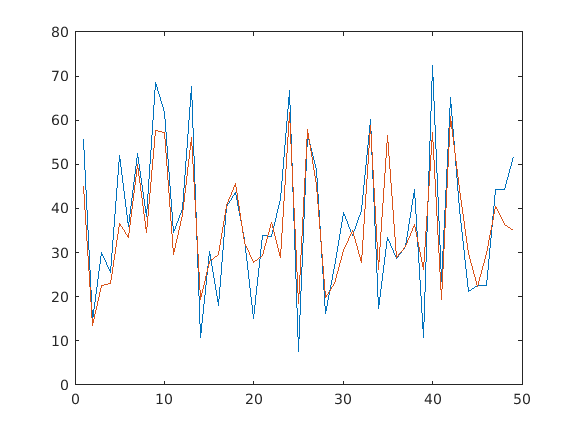

plot(my_predictions)